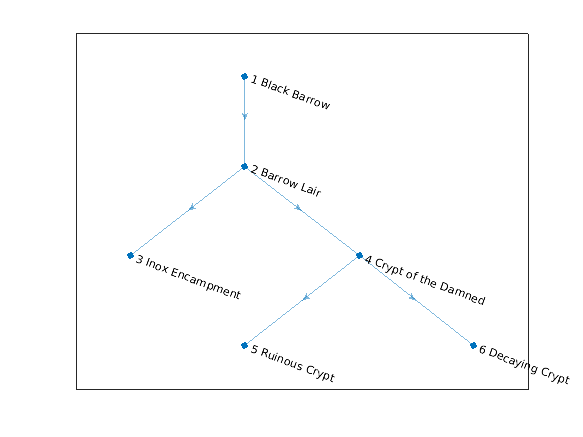

% 1. Create adjacency matrix of all the scenarios we have so far
% 2. Allow a user to input which scenario they have
% completed and what scenario it links to
% 3. Allow a user to ask about information regarding one scenario and
% highlight how they got there
% 4. Show a user the order in which they completed scenarios

edgefields = ["EndNodes","Type","Completed"];
nodefields = ["Name","IsComplete"];
G = digraph(table(["1 Black Barrow", "2 Barrow Lair"], "Actual", "No", ...
    'VariableNames',edgefields), ...
    table(["1 Black Barrow", "2 Barrow Lair"]', ["No", "No"]', ...
    'VariableNames', nodefields));
G = G.addnode(table("3 Inox Encampment", "No", ...
    'VariableNames', nodefields));
G = G.addedge(table(["2 Barrow Lair", "3 Inox Encampment"], "Actual", "No", ...
    'VariableNames', edgefields));
G = G.addnode(table("4 Crypt of the Damned", "No", ...
    'VariableNames', nodefields));
G = G.addedge(table(["2 Barrow Lair", "4 Crypt of the Damned"], "Actual", "No", ...
    'VariableNames', edgefields));
save('data/gloomTree.mat', 'G');
%fullG = G;
%save('data/fullGloomTree.mat', 'fullG');

%G = addLocation("4 Crypt of the Damned", ["5 Ruinous Crypt", "6 Decaying Crypt"]);

p = plot(G);

%save('data/gloomPlot.mat', 'p');
completedArray = string.empty;
save('data/completed.mat', 'completedArray');